[**MIT License**](https://github.com/cdslaborg/paramonte#license)

[**ParaMonte: plain powerful parallel Monte Carlo library**](https://github.com/cdslaborg/paramonte)**.**

**Copyright (C) 2012-present, **[**The Computational Data Science Lab**](https://www.cdslab.org/#about)

[**https://github.com/cdslaborg/paramonte**](https://github.com/cdslaborg/paramonte)

# Making a 2D grid of subplots with the ParaMonte visualization tools

**NOTE**

If you are viewing an HTML version of this MATLAB live script on the web, you can download the corresponding MATLAB live script `visualization_grid.mlx` file to this HTML page at,

[https://github.com/cdslaborg/paramontex/tree/main/MATLAB/mlx](https://github.com/cdslaborg/paramontex/tree/main/MATLAB/mlx)

Once you download the file, open it in MATLAB to view and interact with its contents, which is the same as what you see on this page. 

First, let's clean up the MATLAB environment and make sure the path to the ParaMonte library is in MATLAB's path list.

clc;
clear all;
close all;
format compact; format long;

%%%%%%%%%%%% IMPORTANT %%%%%%%%%%%%%
% Set the path to the ParaMonte library:
% Change the following path to the ParaMonte library root directory, 
% otherwise, make sure the path to the ParaMonte library is already added
% to MATLAB's path list.

pmlibRootDir = './';
addpath(genpath(pmlibRootDir),"-begin");
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% change MATLAB's working directory to the folder containing this script
% if MATLAB Live Scripts did not create a temporary folder, we would not
% have all of these problems!

try
    setwdFilePath = websave("setwd.m","https://github.com/cdslaborg/paramontex/raw/main/MATLAB/mlx/setwd.m");
    run(setwdFilePath); % This is a MATLAB script that you can download from the same GitHub location given in the above.
catch % alas, we will have to run the simulations in MATLAB Live Script's temporary folder
    filePath = mfilename('fullpath');
    [currentDir,fileName,fileExt] = fileparts(filePath); cd(currentDir);
    cd(fileparts(mfilename('fullpath'))); % Change working directory to source code directory.
end

## ParaMonte's default visualization tools

The ParaMonte library ships with several visualization tools that automate much of the MATLAB coding required to visualize the output of the simulations performed by the ParMonte library samplers. 

By replacing the input dataFrame to these tools and following the conventions of the ParaMonte library, one can also use these visualization tools for any dataset that may not have been generated by the ParaMonte library.

Consider the following Markov chain on the web in **compact** format generated by the **ParaDRAM** sampler of the ParaMonte library to sample a MultiVariate Normal distribution. Since this is a chain file as inidicated by its suffix `"_chain.txt"` We will read this file via the ParaDRAM sampler's `readChain()` method.

pm = paramonte();
pmpd = pm.ParaDRAM();
url = "https://github.com/cdslaborg/paramontex/raw/main/MATLAB/mlx/sampling_multivariate_normal_distribution_via_paradram/out/mvn_serial_process_1_chain.txt";
pmpd.readChain(url); % read the chain file from the web


ParaDRAM - WARNING: The ParaDRAM input simulation specification `pmpd.spec.outputDelimiter` is not set.
ParaDRAM - WARNING: This information is essential for successful reading of the requested chain file(s).
ParaDRAM - WARNING: Proceeding with the default assumption of comma-delimited chain file contents...

ParaDRAM - NOTE: 1 files detected matching the pattern: 
ParaDRAM - NOTE: "https://github.com/cdslaborg/paramontex/raw/master/MATLAB/mlx/sampling_multivariate_normal_distribution_via_paradram/out/mvn_serial_process_1_chain.txt"

ParaDRAM - NOTE: processing file: "D:\Dropbox\Projects\20180101_ParaMonte\paramontex\MATLAB\mlx\visualization\temp_20201004_035626_089.txt"
ParaDRAM - NOTE: reading the file contents... 
ParaDRAM - NOTE: done in 0.400880 seconds.
ParaDRAM - NOTE: ndim = 4, count = 50000

ParaDRAM - NOTE: computing the sample correlation matrix...

ParaDRAM - NOTE: creating the heatmap plot object from scratch...
ParaDRAM - NOTE: done in 0.441810 seconds.
ParaDRAM - NOTE: 

This method automatically generates a set of tools that can be used to visualize the contents of the compact chain file. Note that these visualization tools are not unique to this particular method of the ParaDRAM sampler or other ParaMonte samplers. For the sake of illustration however, we will create plots using the above dataset read via `readChain()` method of the ParaDRAM routine.

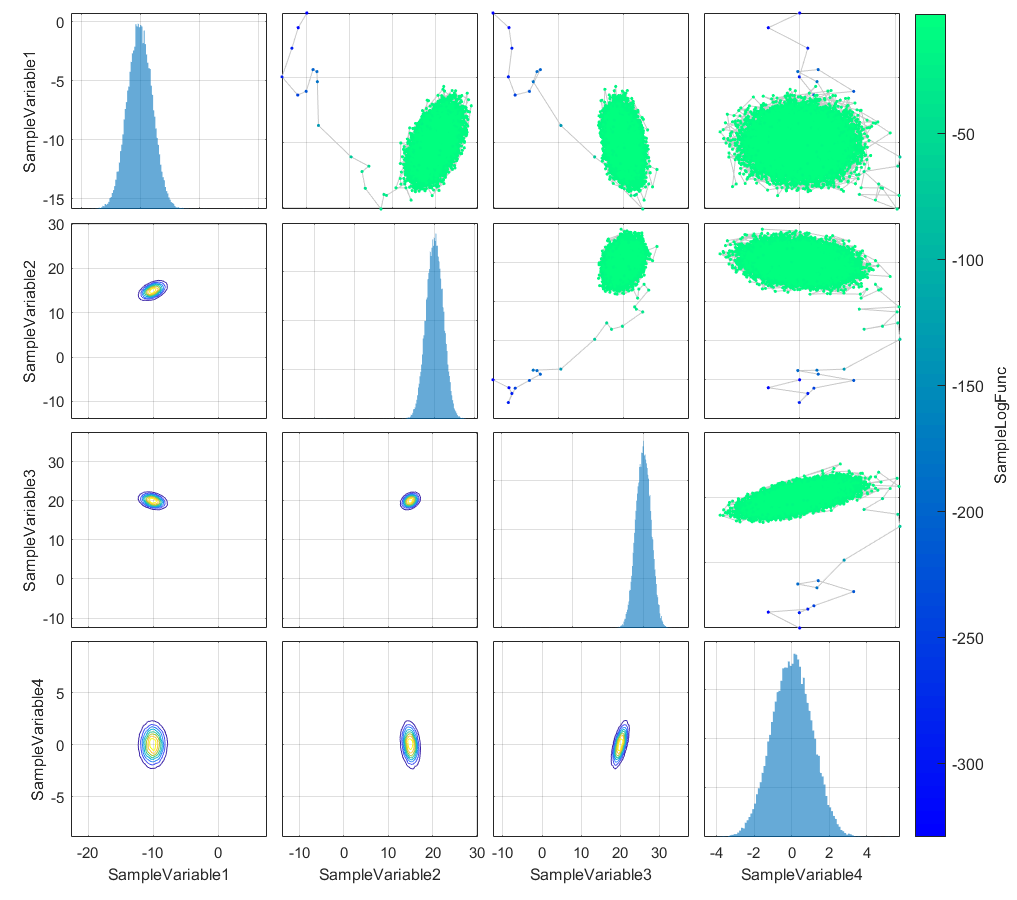

generating subplot #1: (1,1) out of 16
generating subplot #2: (1,2) out of 16
generating subplot #3: (1,3) out of 16
generating subplot #4: (1,4) out of 16
generating subplot #5: (2,1) out of 16
generating subplot #6: (2,2) out of 16
generating subplot #7: (2,3) out of 16
generating subplot #8: (2,4) out of 16
generating subplot #9: (3,1) out of 16
generating subplot #10: (3,2) out of 16
generating subplot #11: (3,3) out of 16
generating subplot #12: (3,4) out of 16
generating subplot #13: (4,1) out of 16
generating subplot #14: (4,2) out of 16
generating subplot #15: (4,3) out of 16
generating subplot #16: (4,4) out of 16


chain = pmpd.chainList{1};
chain.plot.grid.make("columns", 8:11); % choose these column indices to draw from the dataFrame

Be default, the visualization tools are loaded with a set of predefined settings. For example, ParaMonte visualizations are by default colored (unless mutiple variables are to be displayed). These however, can be readily changed. For example, to change the colormap,

chain.plot.grid.colormap

ans = struct with fields:
    enabled: 1
     values: []

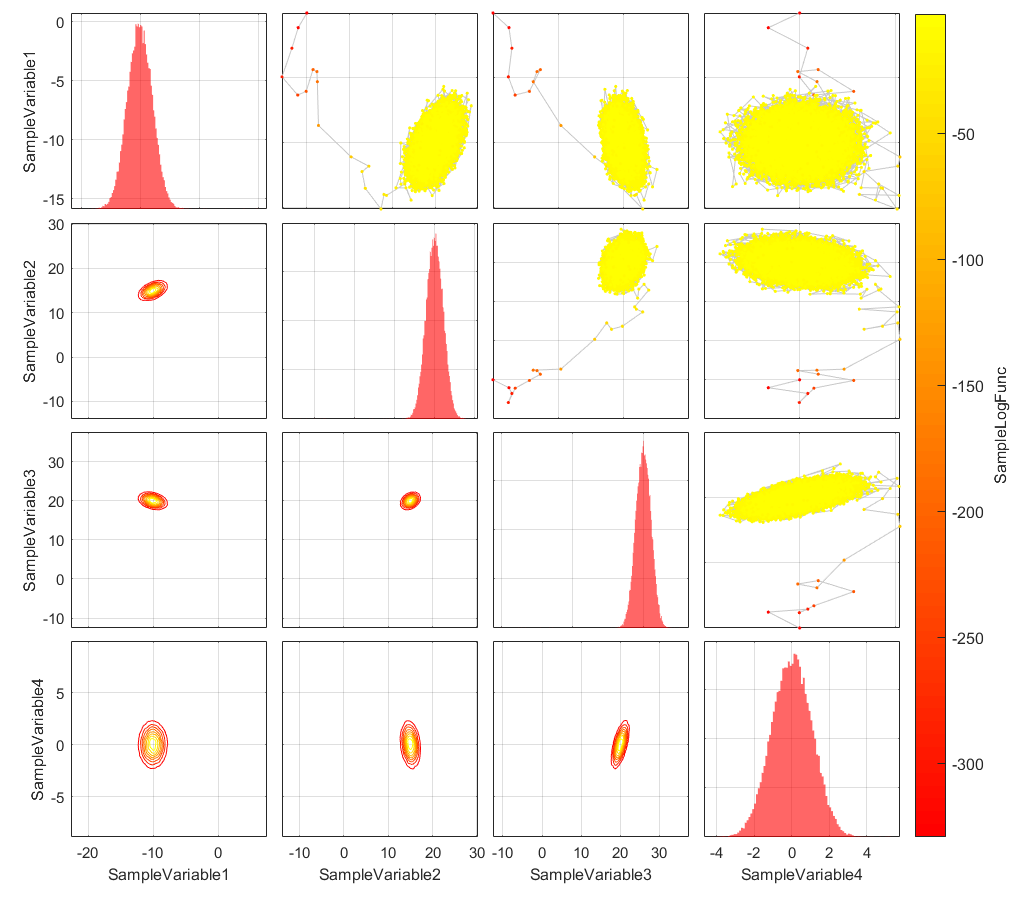

generating subplot #1: (1,1) out of 16
generating subplot #2: (1,2) out of 16
generating subplot #3: (1,3) out of 16
generating subplot #4: (1,4) out of 16
generating subplot #5: (2,1) out of 16
generating subplot #6: (2,2) out of 16
generating subplot #7: (2,3) out of 16
generating subplot #8: (2,4) out of 16
generating subplot #9: (3,1) out of 16
generating subplot #10: (3,2) out of 16
generating subplot #11: (3,3) out of 16
generating subplot #12: (3,4) out of 16
generating subplot #13: (4,1) out of 16
generating subplot #14: (4,2) out of 16
generating subplot #15: (4,3) out of 16
generating subplot #16: (4,4) out of 16


chain.plot.grid.colormap.values = autumn;
chain.plot.grid.template.histogram.histogram.kws.faceColor = "red";
chain.plot.grid.make()

To draw the 2d grid of subplots kernel density estimate plots, the ParaMonte visualizer utilizes a wide array of MATLAB builtin plotting tools. The fundamental types of plots that can be added to the individual subplots in grdi plot and their properties are listed in the `template` component of the grid plot object. Set the properties of different types of subplots via this component. 

The types of plots that are drawn in the upper and lower triangles of the grid plot as well as its diagonal subplots are given in the `plotType` component of the grid plot. For example,

chain.plot.grid.plotType

ans = struct with fields:
    upper: [1×1 struct]
    lower: [1×1 struct]
     diag: [1×1 struct]

chain.plot.grid.plotType.diag

ans = struct with fields:
    enabled: 1
      value: "histogram"
      names: ["histogram"    "histfit"]

chain.plot.grid.plotType.diag.names % these are the names of possible plot types that can appear in the diagonal elements of the grid plot.

ans = 1×2 string array
    "histogram"    "histfit"

chain.plot.grid.plotType.diag.value % this is the name of the current plot type in the diagonal subplots.

ans = "histogram"

chain.plot.grid.plotType.diag.value = "histfit"; % choose histfit for the diagonal subplots

 This will cause the diagonal elements of the grid plot to become histograms with distribution fits via MATLAB's builtin `histfit()` function. By default, the fitted distribution is `"Normal"`, but this can be changed if needed,

chain.plot.grid.template.histfit.histfit.dist

ans = "Normal"

chain.plot.grid.colormap.values = "autumn";
chain.plot.grid.make();

generating subplot #1: (1,1) out of 16
generating subplot #2: (1,2) out of 16
generating subplot #3: (1,3) out of 16
generating subplot #4: (1,4) out of 16
generating subplot #5: (2,1) out of 16
generating subplot #6: (2,2) out of 16
generating subplot #7: (2,3) out of 16
generating subplot #8: (2,4) out of 16
generating subplot #9: (3,1) out of 16
generating subplot #10: (3,2) out of 16
generating subplot #11: (3,3) out of 16
generating subplot #12: (3,4) out of 16
generating subplot #13: (4,1) out of 16
generating subplot #14: (4,2) out of 16
generating subplot #15: (4,3) out of 16
generating subplot #16: (4,4) out of 16


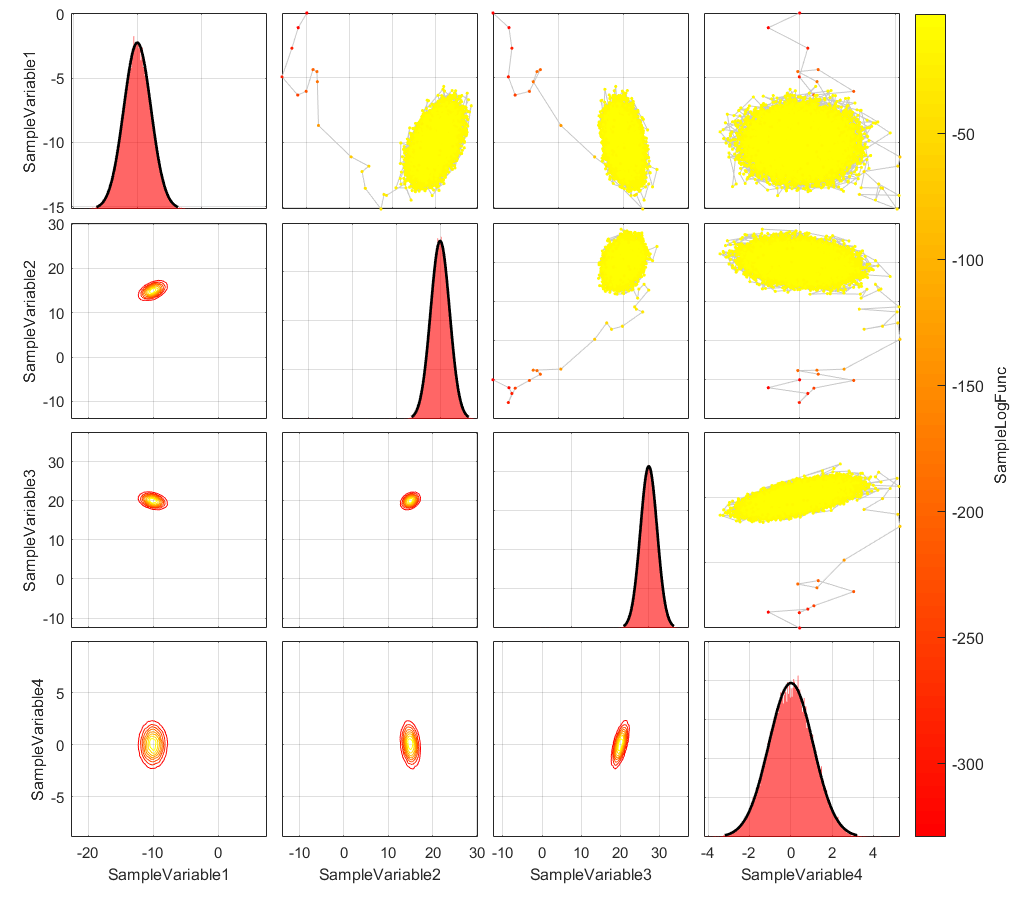

for i = 1:length(chain.plot.grid.columns) % now change the colors of hisfit subplots to red.
    chain.plot.grid.currentFig.subplotList{i,i}.currentFig.histfit{1}(1).FaceColor = "red";
end

To **reset** the properties of the plot object to the default settings, try, 

chain.plot.grid.reset();

ParaDRAM - NOTE: resetting the properties of the grid plot...


To reset the entire plot object including reading the data again from the input dataFrame, try, 

chain.plot.grid.reset("hard");

ParaDRAM - NOTE: creating the grid plot object from scratch...


Similarly, to change the properties of the **colorbar**, try, 

chain.plot.grid.colorbar.kws

ans = struct with fields:
    fontSize: 12

chain.plot.grid.colorbar.kws.fontSize = 13;

Remember that a handle to all objects in the plot is also stored in the `currentFig` component of the object. Most of the properties of the figure, axes, and the plots can be also changed directly via these handles. For example, to set the label to somethign other than the default (which is taken from the `ccolumn` component's value), one could try, 

chain.plot.grid.make("columns", 8:10);

generating subplot #1: (1,1) out of 9
generating subplot #2: (1,2) out of 9
generating subplot #3: (1,3) out of 9
generating subplot #4: (2,1) out of 9
generating subplot #5: (2,2) out of 9
generating subplot #6: (2,3) out of 9
generating subplot #7: (3,1) out of 9
generating subplot #8: (3,2) out of 9
generating subplot #9: (3,3) out of 9


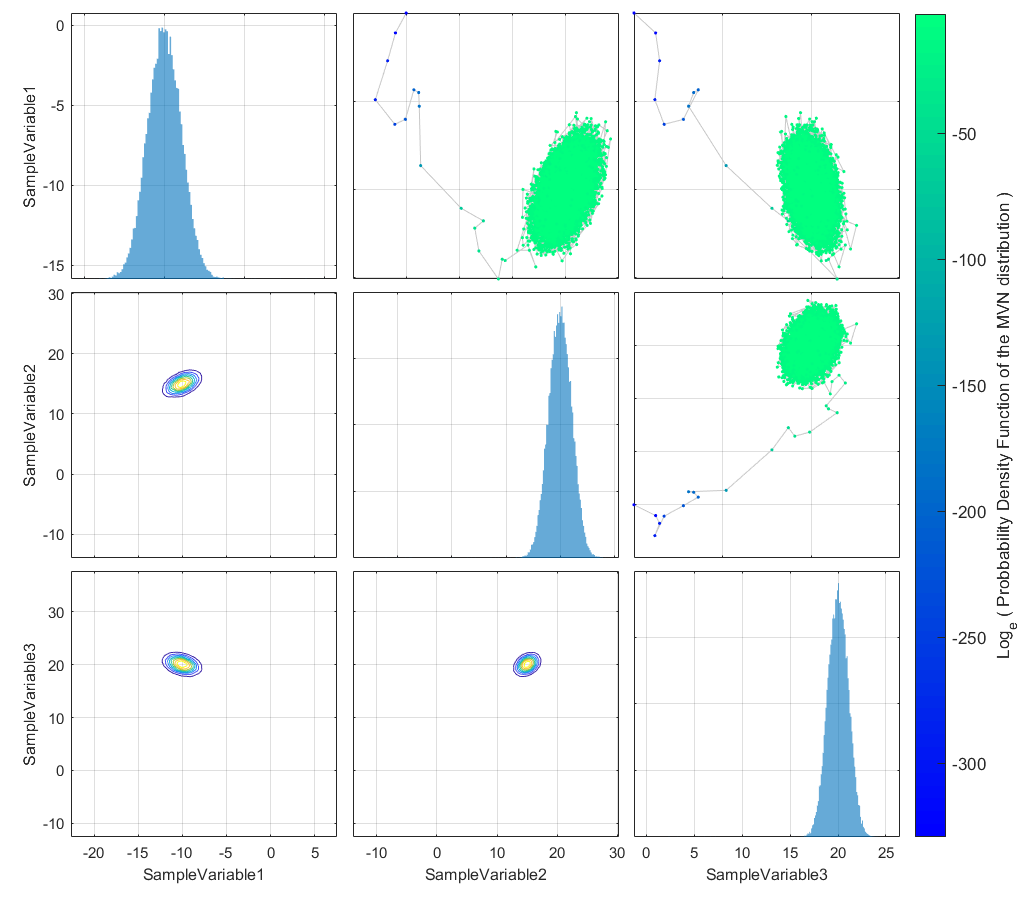

chain.plot.grid.currentFig.colorbar.Label.Interpreter = "tex";
chain.plot.grid.currentFig.colorbar.Label.FontSize = 13;
chain.plot.grid.currentFig.colorbar.Label.String = "Log_e ( Probbability Density Function of the MVN distribution )";

## Plotting only one traingle of the grid plot

It is possible to disable some part of the grid plot via the `plotType` attribute of the grid plot. For example, to disable the upper plot and show only lineScatter plots on the lower half,

chain.plot.grid.reset();

ParaDRAM - NOTE: resetting the properties of the grid plot...


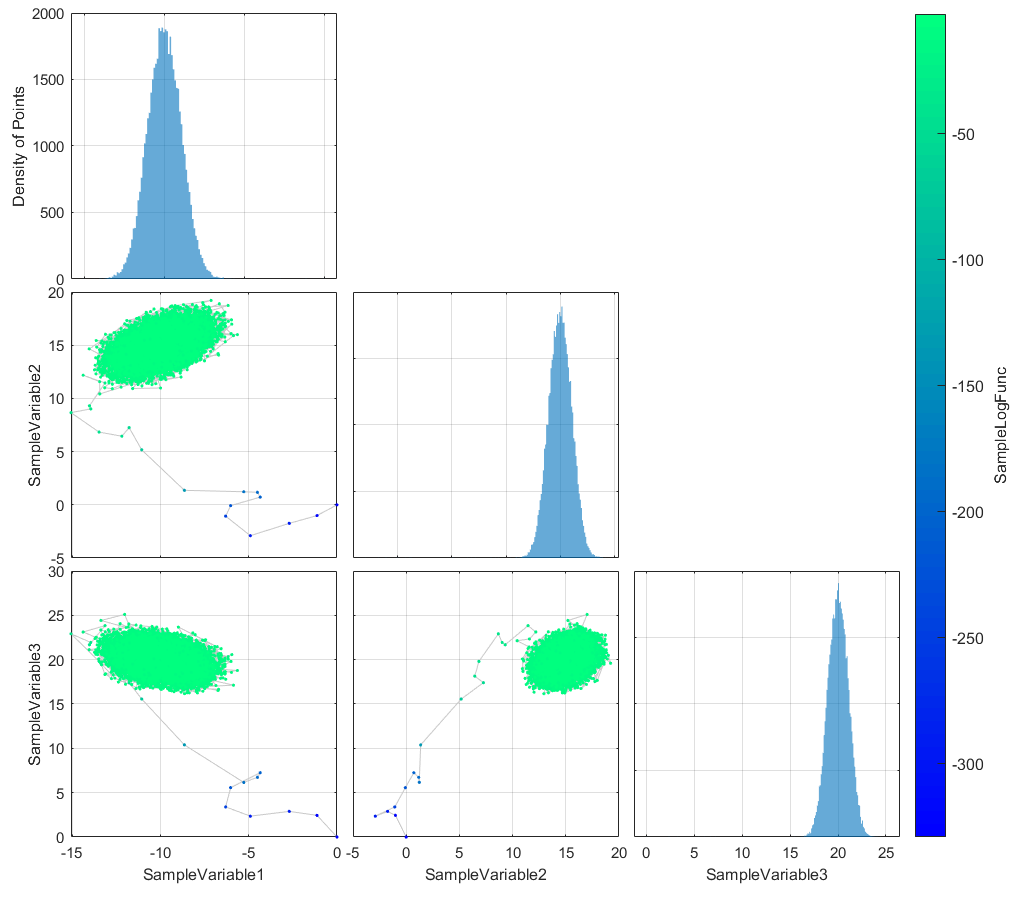

generating subplot #1: (1,1) out of 9
skipping   subplot #2: (1,2) out of 9
skipping   subplot #3: (1,3) out of 9
generating subplot #4: (2,1) out of 9
generating subplot #5: (2,2) out of 9
skipping   subplot #6: (2,3) out of 9
generating subplot #7: (3,1) out of 9
generating subplot #8: (3,2) out of 9
generating subplot #9: (3,3) out of 9


chain.plot.grid.plotType.upper.enabled = false;
chain.plot.grid.plotType.lower.value = "lineScatter";
chain.plot.grid.make("columns", ["SampleVariable1",9:10]);

  or the other way, around,

chain.plot.grid.reset();

ParaDRAM - NOTE: resetting the properties of the grid plot...


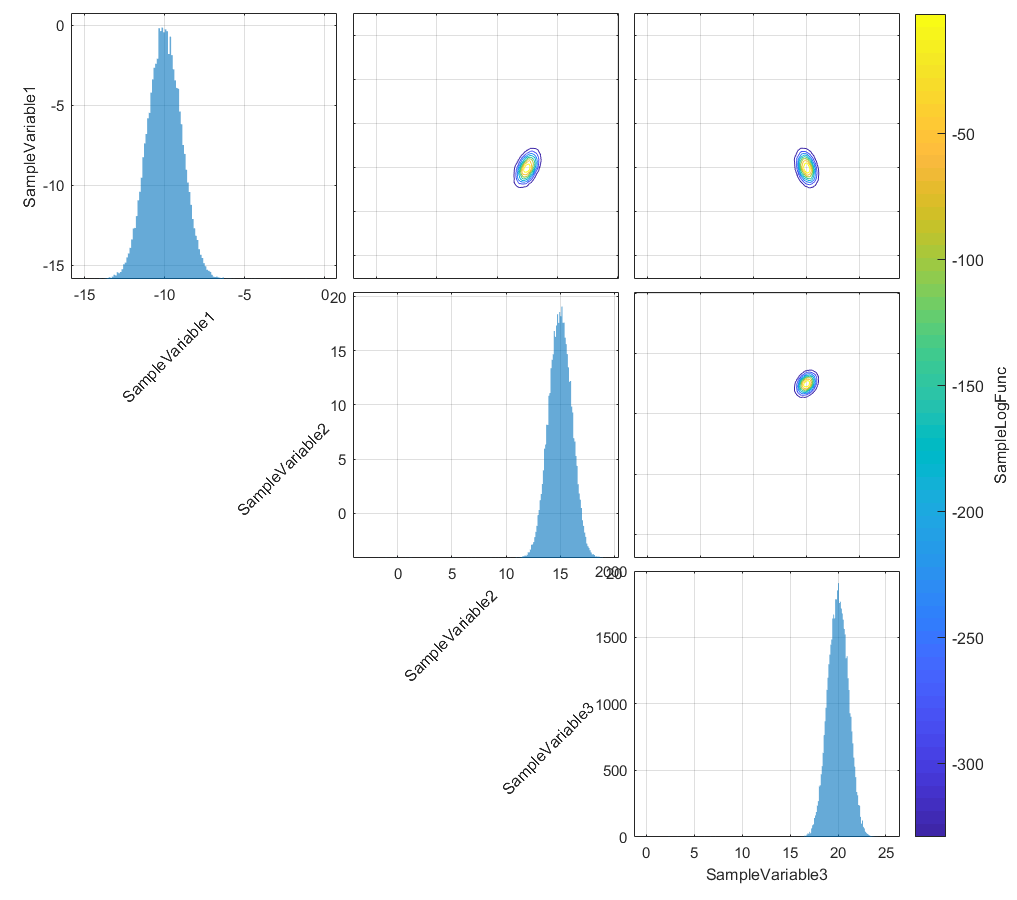

generating subplot #1: (1,1) out of 9
generating subplot #2: (1,2) out of 9
generating subplot #3: (1,3) out of 9
skipping   subplot #4: (2,1) out of 9
generating subplot #5: (2,2) out of 9
generating subplot #6: (2,3) out of 9
skipping   subplot #7: (3,1) out of 9
skipping   subplot #8: (3,2) out of 9
generating subplot #9: (3,3) out of 9


chain.plot.grid.plotType.lower.enabled = false;
chain.plot.grid.plotType.upper.value = "contour";
chain.plot.grid.make("columns", ["SampleVariable1",9:10]);

Notice the automatic change in the colorbar, which is now switched to the colormapping of the kernel density plots, in the abcense of lineScatter plots.

It also possible to hide some part of the plot after the plot is complete, 

chain.plot.grid.reset();

ParaDRAM - NOTE: resetting the properties of the grid plot...


chain.plot.grid.make("columns", ["SampleVariable1",9:10]);

generating subplot #1: (1,1) out of 9
generating subplot #2: (1,2) out of 9
generating subplot #3: (1,3) out of 9
generating subplot #4: (2,1) out of 9
generating subplot #5: (2,2) out of 9
generating subplot #6: (2,3) out of 9
generating subplot #7: (3,1) out of 9
generating subplot #8: (3,2) out of 9
generating subplot #9: (3,3) out of 9


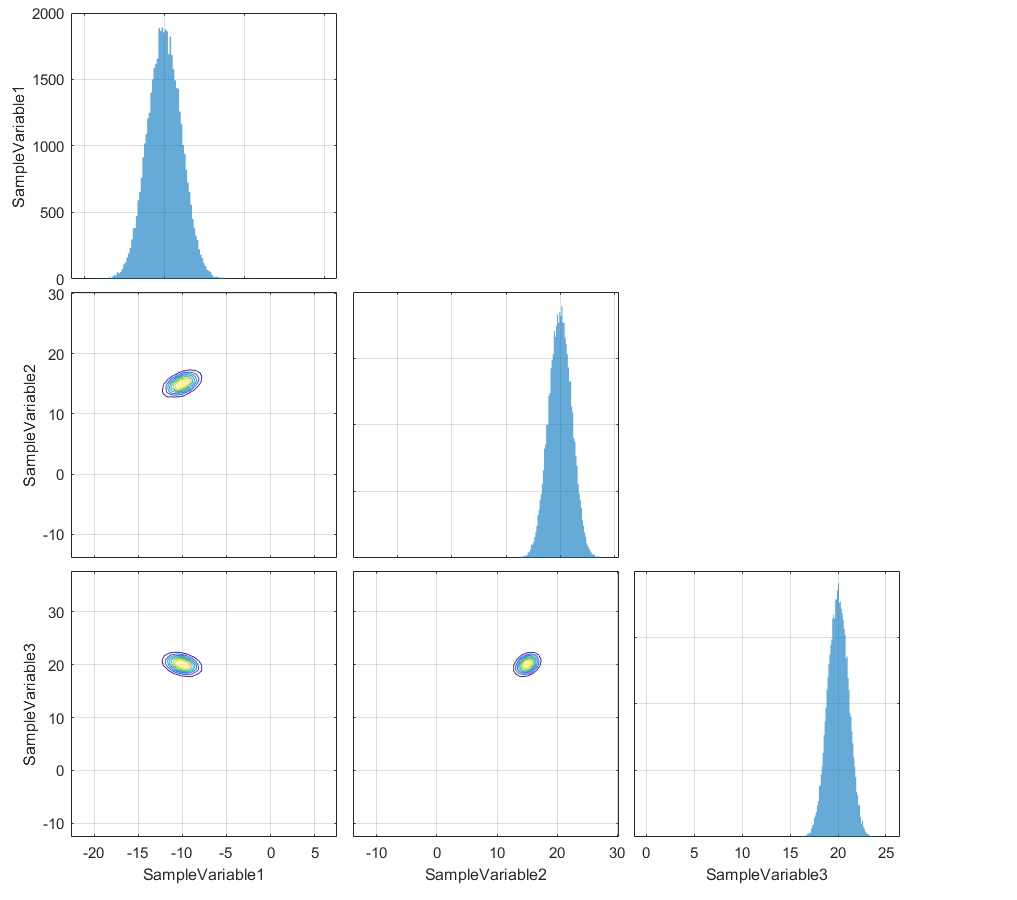

chain.plot.grid.hide("upper") % other possible inputs: "lower", "diag", "colorbar" or "cbar"
chain.plot.grid.hide("colorbar")

or, perhapse we change our mind and want show the hidden part and hide the diagonals instead,

chain.plot.grid.reset();

ParaDRAM - NOTE: resetting the properties of the grid plot...


chain.plot.grid.make("columns", 8:11);

generating subplot #1: (1,1) out of 16
generating subplot #2: (1,2) out of 16
generating subplot #3: (1,3) out of 16
generating subplot #4: (1,4) out of 16
generating subplot #5: (2,1) out of 16
generating subplot #6: (2,2) out of 16
generating subplot #7: (2,3) out of 16
generating subplot #8: (2,4) out of 16
generating subplot #9: (3,1) out of 16
generating subplot #10: (3,2) out of 16
generating subplot #11: (3,3) out of 16
generating subplot #12: (3,4) out of 16
generating subplot #13: (4,1) out of 16
generating subplot #14: (4,2) out of 16
generating subplot #15: (4,3) out of 16
generating subplot #16: (4,4) out of 16


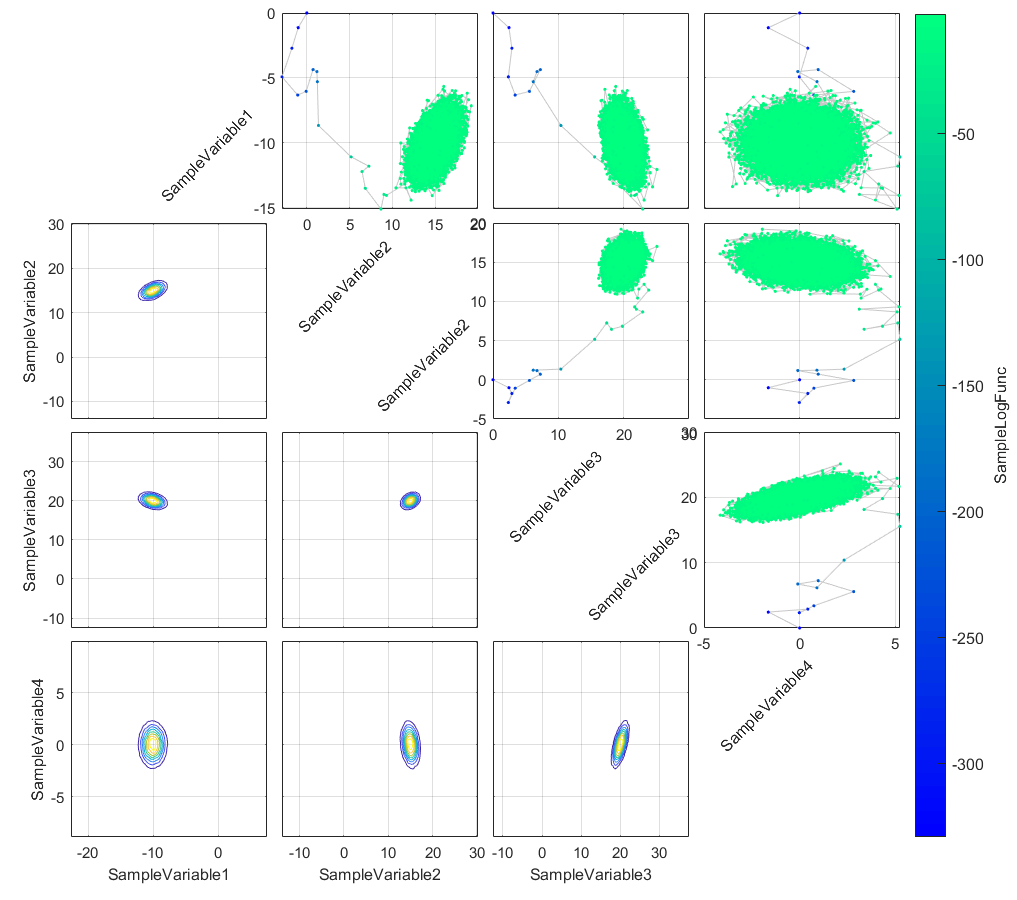

chain.plot.grid.hide("upper")
chain.plot.grid.hide("diag")
chain.plot.grid.show("upper") % other possible inputs: "lower", "diag", "colorbar"

To show or hide all objects in the plot at once, try `hide()` or `show()` methods without input arguments.

## Setting the template properties of the subplots

The properties of any group of subplots that are of the same type can be set via the components of the `template` component,

chain.plot.grid.template

ans = struct with fields:
        histfit: [1×1 struct]
      histogram: [1×1 struct]
        contour: [1×1 struct]
       contourf: [1×1 struct]
    lineScatter: [1×1 struct]

These property settings are reflected in subplots of the same type. If one particular subplot has to be individually modified, try accessing the properties of that plot via the `subplotList` component of the `currentFig` component of the grid plot. For example, to access the properties of the top-right subplot, try,

chain.plot.grid.currentFig.subplotList{1,end}

ans =   LineScatterPlot with properties:

      ccolumns: "SampleLogFunc"
      colorbar: [1×1 struct]
      colormap: [1×1 struct]
         dfref: [50000×11 table]
        figure: [1×1 struct]
    currentFig: [1×1 struct]
      ycolumns: "SampleVariable1"
       surface: [1×1 struct]
       scatter: [1×1 struct]
          rows: [1×50000 double]
      xcolumns: "SampleVariable4"
        target: [1×1 Target_class]
          axes: [1×1 struct]
          plot: [1×1 struct]
        legend: [1×1 struct]

To access the properties of the bottom-left subplot, try, 

chain.plot.grid.currentFig.subplotList{end,1}

ans =   DensityPlot with properties:

      xcolumns: "SampleVariable1"
         dfref: [50000×11 table]
        figure: [1×1 struct]
    currentFig: [1×1 struct]
      ycolumns: "SampleVariable4"
       contour: [1×1 struct]
      colormap: [1×1 struct]
      colorbar: [1×1 struct]
          rows: [1×50000 double]
      gridSize: 512
        target: [1×1 Target_class]
    noiseLevel: 1.000000000000000e-03
          axes: [1×1 struct]
      ccolumns: "SampleLogFunc"
        legend: [1×1 struct]

The same holds for all other subplots in the grid.

## Changing the data column used for colormapping

The `ccolumn` property specified what data column has to be used for colormapping of the lineScatter subplots. By default, the column `"SampleLogFunc"` if it exists in the dataFrame, is used to colormap the subplots, but this can be readily changed to any column name of the dataFrame or to nothing, in which case, the dataFrame's row indices will be used ,

chain.plot.grid.reset();

ParaDRAM - NOTE: resetting the properties of the grid plot...


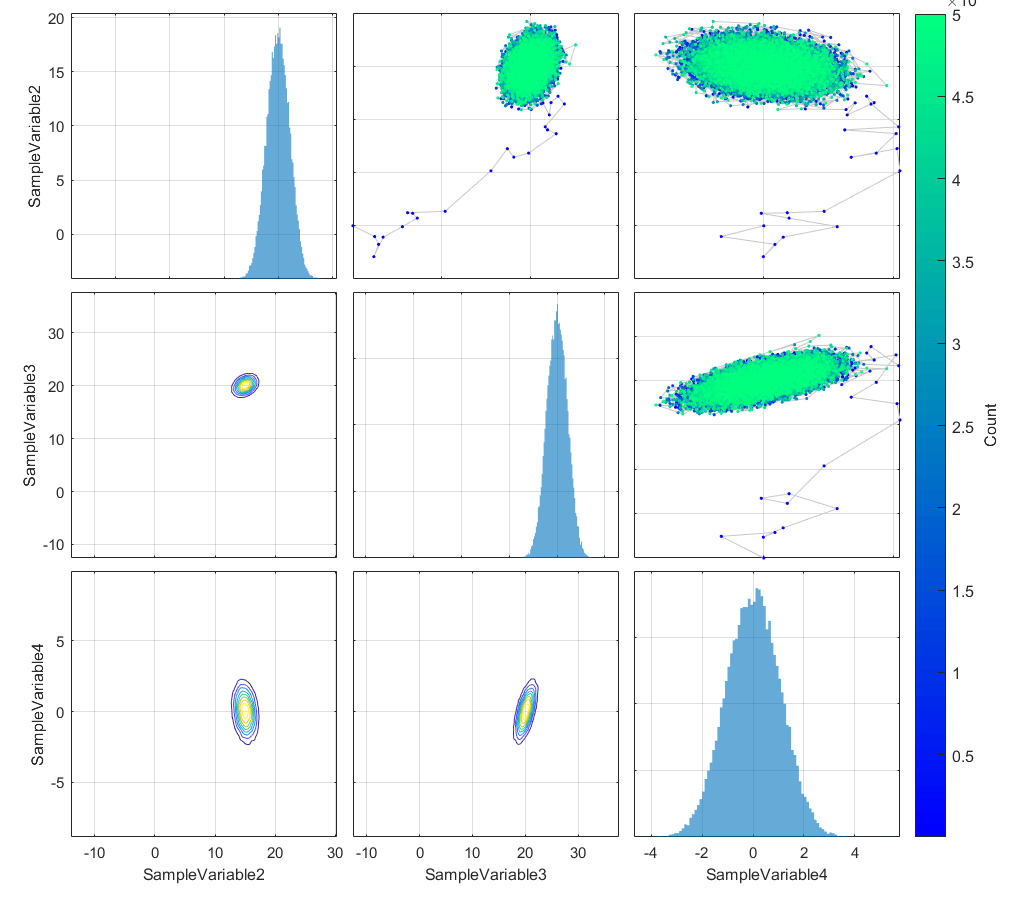

generating subplot #1: (1,1) out of 9
generating subplot #2: (1,2) out of 9
generating subplot #3: (1,3) out of 9
generating subplot #4: (2,1) out of 9
generating subplot #5: (2,2) out of 9
generating subplot #6: (2,3) out of 9
generating subplot #7: (3,1) out of 9
generating subplot #8: (3,2) out of 9
generating subplot #9: (3,3) out of 9

the component "ccolumn" of the GridPlot object appears to be empty. Using the data counts instead for colormapping...



chain.plot.grid.ccolumn = []; % use the order of points in the dataFrame as the color
chain.plot.grid.make("columns", 9:11);

## Unicolor plot

Alternative, one could **turn off the colormapping completely** via,

chain.plot.grid.reset();

ParaDRAM - NOTE: resetting the properties of the grid plot...


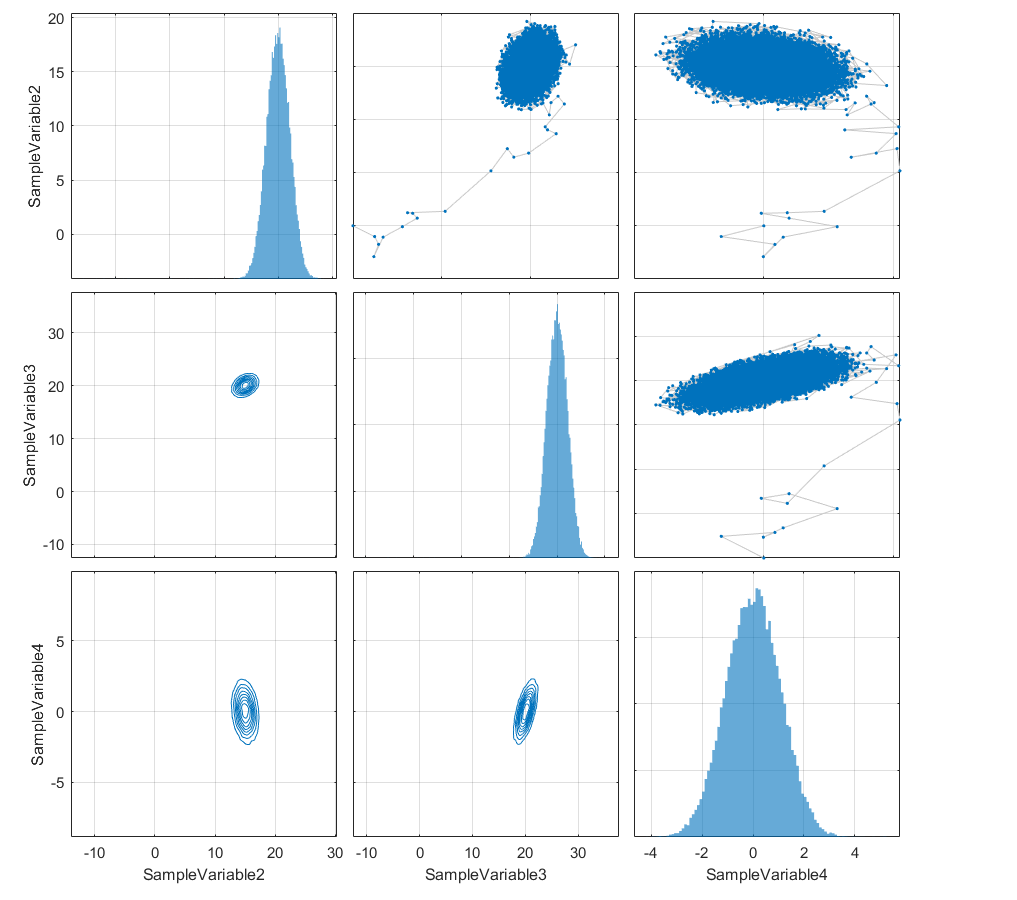

generating subplot #1: (1,1) out of 9
generating subplot #2: (1,2) out of 9
generating subplot #3: (1,3) out of 9
generating subplot #4: (2,1) out of 9
generating subplot #5: (2,2) out of 9
generating subplot #6: (2,3) out of 9
generating subplot #7: (3,1) out of 9
generating subplot #8: (3,2) out of 9
generating subplot #9: (3,3) out of 9


chain.plot.grid.colormap.enabled = false;
chain.plot.grid.make("columns", 9:11);

## Plotting specific rows of data

Selected rows of data can be also plotted, if not all data observations have to be included. For example, we can exclude the burnin episode as determined by the ParaMonte sampler, 

chain.plot.grid.reset();

ParaDRAM - NOTE: resetting the properties of the grid plot...


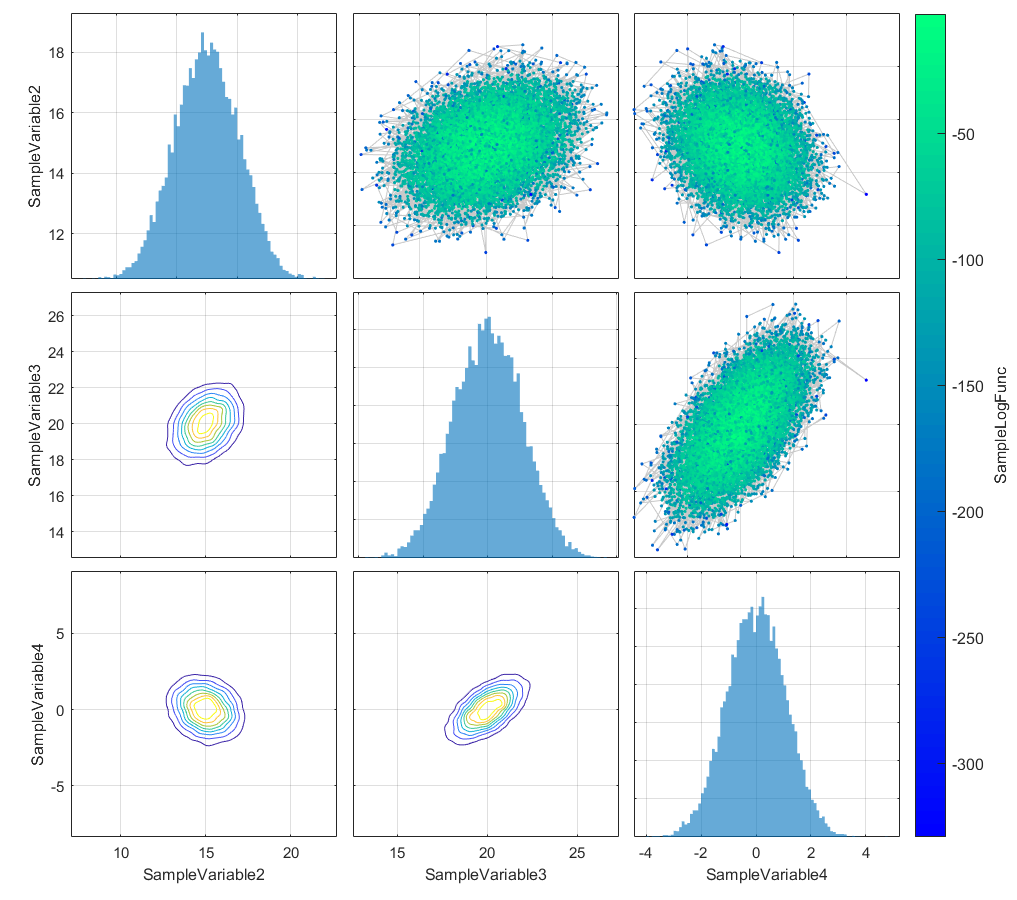

generating subplot #1: (1,1) out of 9
generating subplot #2: (1,2) out of 9
generating subplot #3: (1,3) out of 9
generating subplot #4: (2,1) out of 9
generating subplot #5: (2,2) out of 9
generating subplot #6: (2,3) out of 9
generating subplot #7: (3,1) out of 9
generating subplot #8: (3,2) out of 9
generating subplot #9: (3,3) out of 9


burnin = chain.df.BurninLocation(end); % get the inferred burning location at the end of the chain

chain.plot.grid.rows = burnin:3:chain.count; % plot every one out of 10 data rows, starting from the burnin location to the end of the chain.
chain.plot.grid.make();

## Rotating the axes labels

Sometimes, due to the large number of columns to be plotted, the axes labels have to be rotated such that they all fit well within the boundaries of each subplot. To do so, use the `rotateAxesLabels(degreeX, degreeY)` method of the plot object where `degreeX, degreeY` are the amounts of rotations for the X and Y labels with respect to the horizontal line. If not argument is provided, the default angle will be 45 degrees.

chain.plot.grid.reset("hard");

ParaDRAM - NOTE: creating the grid plot object from scratch...


chain.plot.grid.make("rows",burnin:chain.count);

generating subplot #1: (1,1) out of 25
generating subplot #2: (1,2) out of 25
generating subplot #3: (1,3) out of 25
generating subplot #4: (1,4) out of 25
generating subplot #5: (1,5) out of 25
generating subplot #6: (2,1) out of 25
generating subplot #7: (2,2) out of 25
generating subplot #8: (2,3) out of 25
generating subplot #9: (2,4) out of 25
generating subplot #10: (2,5) out of 25
generating subplot #11: (3,1) out of 25
generating subplot #12: (3,2) out of 25
generating subplot #13: (3,3) out of 25
generating subplot #14: (3,4) out of 25
generating subplot #15: (3,5) out of 25
generating subplot #16: (4,1) out of 25
generating subplot #17: (4,2) out of 25
generating subplot #18: (4,3) out of 25
generating subplot #19: (4,4) out of 25
generating subplot #20: (4,5) out of 25
generating subplot #21: (5,1) out of 25
generating subplot #22: (5,2) out of 25
generating subplot #23: (5,3) out of 25
generating subplot #24: (5,4) out of 25
generating subplot #25: (5,5) out of 25


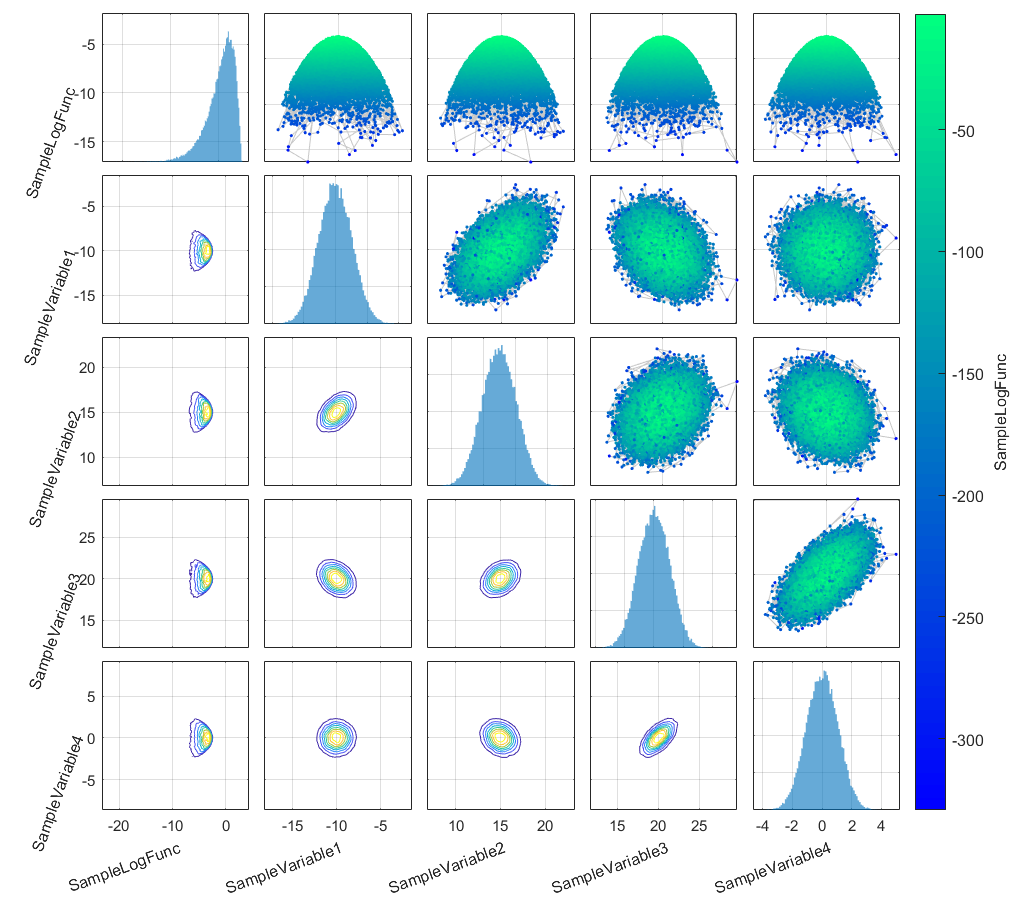

chain.plot.grid.rotateAxesLabels(20,70);
chain.plot.grid.axes.main.margin.left = 0.1; % add the to left margin of the grid plot o create room for the rotated labels.
chain.plot.grid.axes.main.margin.bottom = 0.1; % add the to bottom margin of the grid plot o create room for the rotated labels.
chain.plot.grid.updateLayout(); % update the layout of the grid plot with the new margins.

## Changing the subplot axes labels

While there are multiple ways to set the labels of the subplots, the GridPlot class ships with a method named `setAxesLabels()` that can readily perform this task for us,

chain.plot.grid.reset("hard");

ParaDRAM - NOTE: creating the grid plot object from scratch...


chain.plot.grid.make("columns", 7:10);

generating subplot #1: (1,1) out of 16
generating subplot #2: (1,2) out of 16
generating subplot #3: (1,3) out of 16
generating subplot #4: (1,4) out of 16
generating subplot #5: (2,1) out of 16
generating subplot #6: (2,2) out of 16
generating subplot #7: (2,3) out of 16
generating subplot #8: (2,4) out of 16
generating subplot #9: (3,1) out of 16
generating subplot #10: (3,2) out of 16
generating subplot #11: (3,3) out of 16
generating subplot #12: (3,4) out of 16
generating subplot #13: (4,1) out of 16
generating subplot #14: (4,2) out of 16
generating subplot #15: (4,3) out of 16
generating subplot #16: (4,4) out of 16


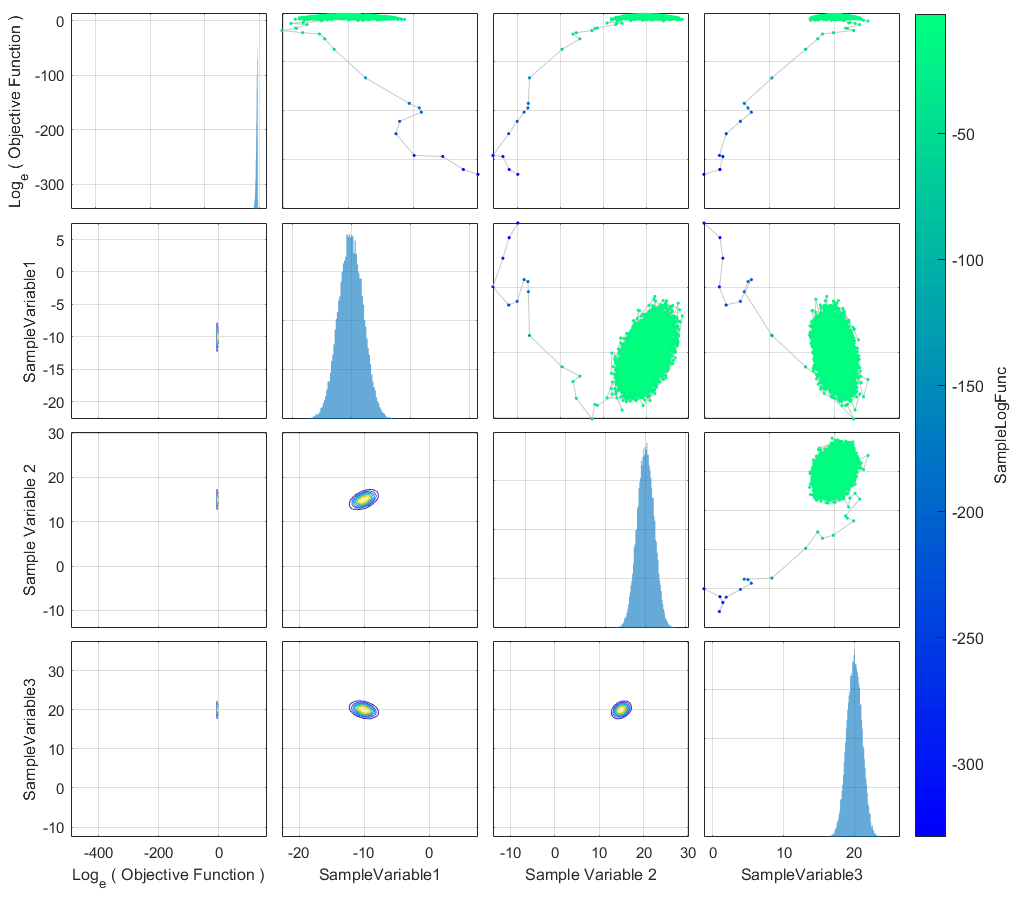

chain.plot.grid.setAxesLabels( { 'Log_e ( Objective Function )', [], 'Sample Variable 2', [] }, "fontSize", 13, "interpreter", "tex" );

Note that passing `[]` instead of a a string or char vector in the input cell array of labels to `setAxesLabels()` leaves the current axis label of the corresponding plot intact. Also note the ability to pass keyword arguments to this method, which are directly passed to the `xlabel()` and `ylabel()` functions of MATLAB.

## Changing the limits of the subplots' axes

While there are multiple ways to set the limits of the subplots' axes, the GridPlot class also provides a method named `setAxesLimits(limits)` which can directly and readily set the limits of axes of the subplots. Similar to the input argument of `setAxesLabels()`, the input argument `limits` to `setAxesLimits()` method is a cell array whose elements are either vectors of length 2 representing the limits of the subplots in the grid plot in the order from top-left to the bottom-right, or, empty objects, in which case, the limists of the axes of the corresponding subplots will not be touched.

chain.plot.grid.reset("hard");

ParaDRAM - NOTE: creating the grid plot object from scratch...


chain.plot.grid.make("columns", 7:10);

generating subplot #1: (1,1) out of 16
generating subplot #2: (1,2) out of 16
generating subplot #3: (1,3) out of 16
generating subplot #4: (1,4) out of 16
generating subplot #5: (2,1) out of 16
generating subplot #6: (2,2) out of 16
generating subplot #7: (2,3) out of 16
generating subplot #8: (2,4) out of 16
generating subplot #9: (3,1) out of 16
generating subplot #10: (3,2) out of 16
generating subplot #11: (3,3) out of 16
generating subplot #12: (3,4) out of 16
generating subplot #13: (4,1) out of 16
generating subplot #14: (4,2) out of 16
generating subplot #15: (4,3) out of 16
generating subplot #16: (4,4) out of 16


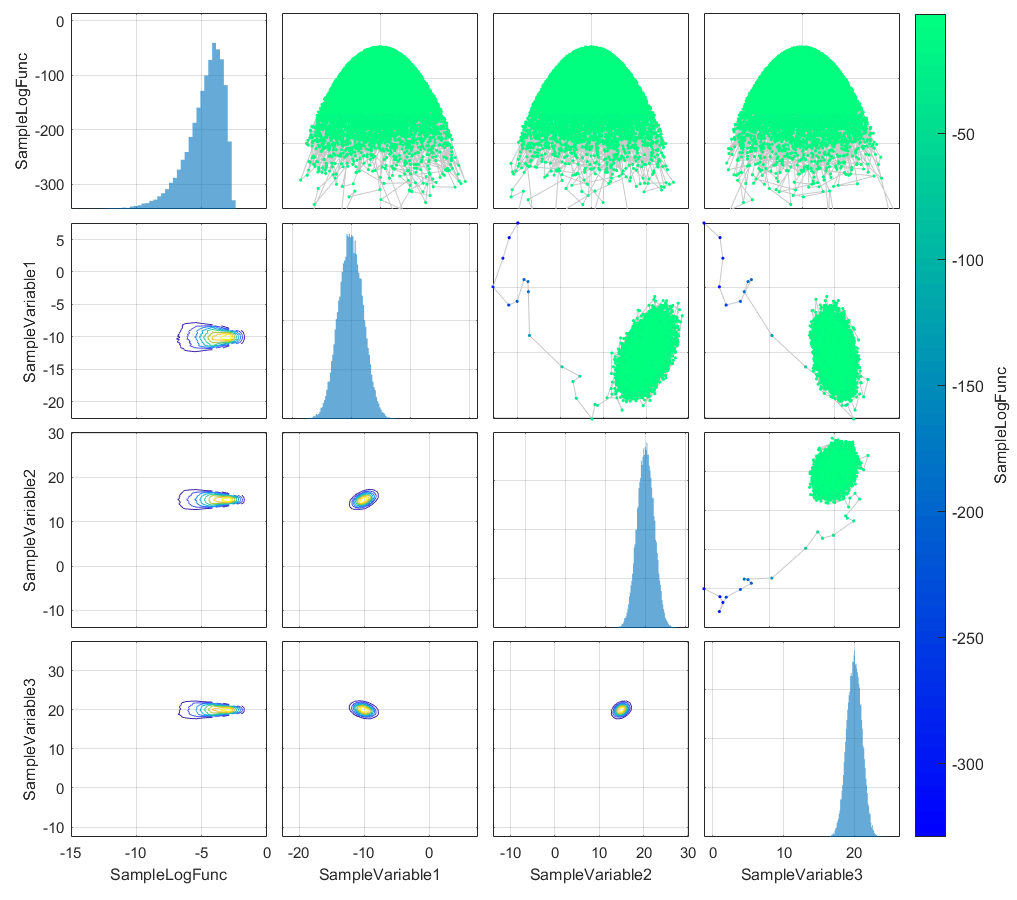

chain.plot.grid.setAxesLimits( { [-15 0], [], [], [] } );

Compare this limits of the first column of this grid plot with the previous grid plot.

## Adding targets to the plot

One can also **add target values** to the plots. There are multiple ways to do. The simplest way is to use the `addTarget()` component of the plot object. By default, the state corresponding to the mode of the `"SampleLogFunc"` column of the dataFrame is preloaded as the target value in this method. Therefore, `addTarget()` is equivalent to `addTarget("mode")`. Other possibilities include, `addTarget("mean")` and `addTarget("median")`. For example, to plot the mode of `"SampleLogFunc"`, try,

chain.plot.grid.reset("hard");

ParaDRAM - NOTE: creating the grid plot object from scratch...


chain.plot.grid.rows = burnin:chain.count;
chain.plot.grid.make();

generating subplot #1: (1,1) out of 25
generating subplot #2: (1,2) out of 25
generating subplot #3: (1,3) out of 25
generating subplot #4: (1,4) out of 25
generating subplot #5: (1,5) out of 25
generating subplot #6: (2,1) out of 25
generating subplot #7: (2,2) out of 25
generating subplot #8: (2,3) out of 25
generating subplot #9: (2,4) out of 25
generating subplot #10: (2,5) out of 25
generating subplot #11: (3,1) out of 25
generating subplot #12: (3,2) out of 25
generating subplot #13: (3,3) out of 25
generating subplot #14: (3,4) out of 25
generating subplot #15: (3,5) out of 25
generating subplot #16: (4,1) out of 25
generating subplot #17: (4,2) out of 25
generating subplot #18: (4,3) out of 25
generating subplot #19: (4,4) out of 25
generating subplot #20: (4,5) out of 25
generating subplot #21: (5,1) out of 25
generating subplot #22: (5,2) out of 25
generating subplot #23: (5,3) out of 25
generating subplot #24: (5,4) out of 25
generating subplot #25: (5,5) out of 25


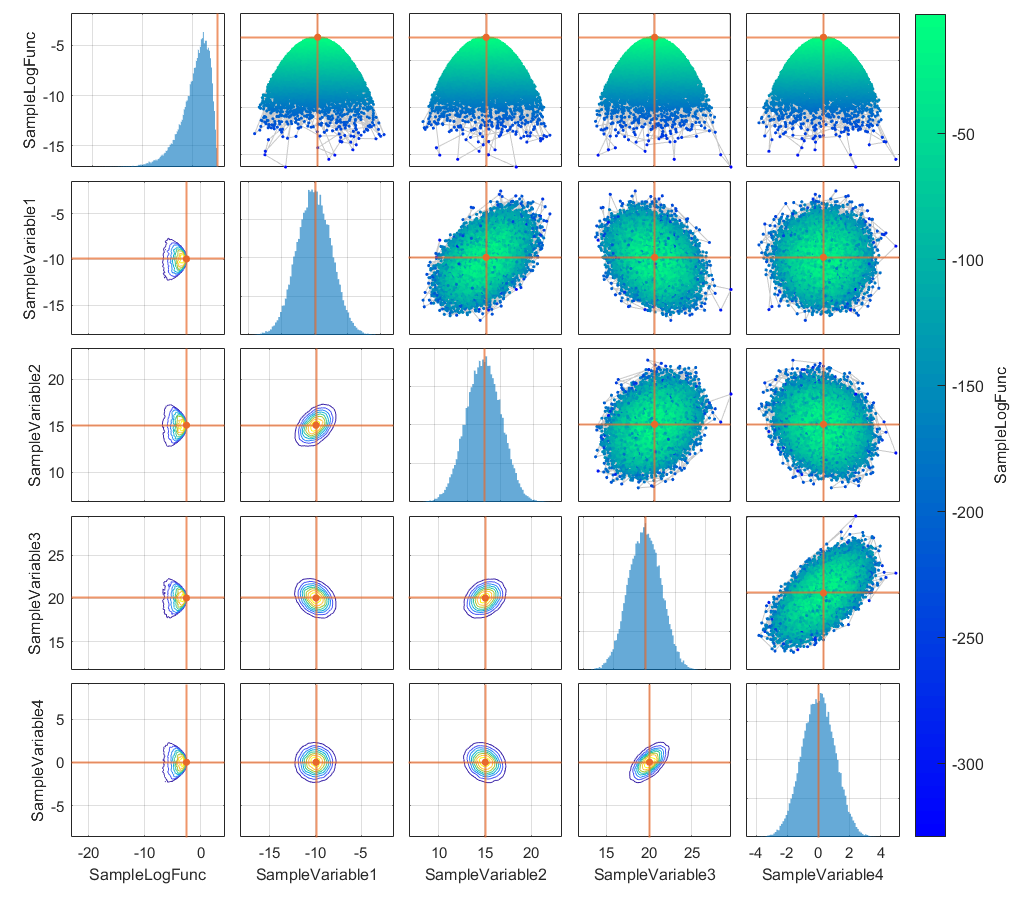

chain.plot.grid.addTarget();

A more elaborate but specific method of adding target to the subplots is via direct manipulation of the target component of the subplots. For example, suppose we were to add the mean and one-sigma standard deviation lines to only the disgonal histogram subplots and no other subplot. We could try,

chain.plot.grid.reset("hard");

ParaDRAM - NOTE: creating the grid plot object from scratch...


chain.plot.grid.rows = burnin:chain.count;
chain.plot.grid.make("columns", 8:11);

generating subplot #1: (1,1) out of 16
generating subplot #2: (1,2) out of 16
generating subplot #3: (1,3) out of 16
generating subplot #4: (1,4) out of 16
generating subplot #5: (2,1) out of 16
generating subplot #6: (2,2) out of 16
generating subplot #7: (2,3) out of 16
generating subplot #8: (2,4) out of 16
generating subplot #9: (3,1) out of 16
generating subplot #10: (3,2) out of 16
generating subplot #11: (3,3) out of 16
generating subplot #12: (3,4) out of 16
generating subplot #13: (4,1) out of 16
generating subplot #14: (4,2) out of 16
generating subplot #15: (4,3) out of 16
generating subplot #16: (4,4) out of 16


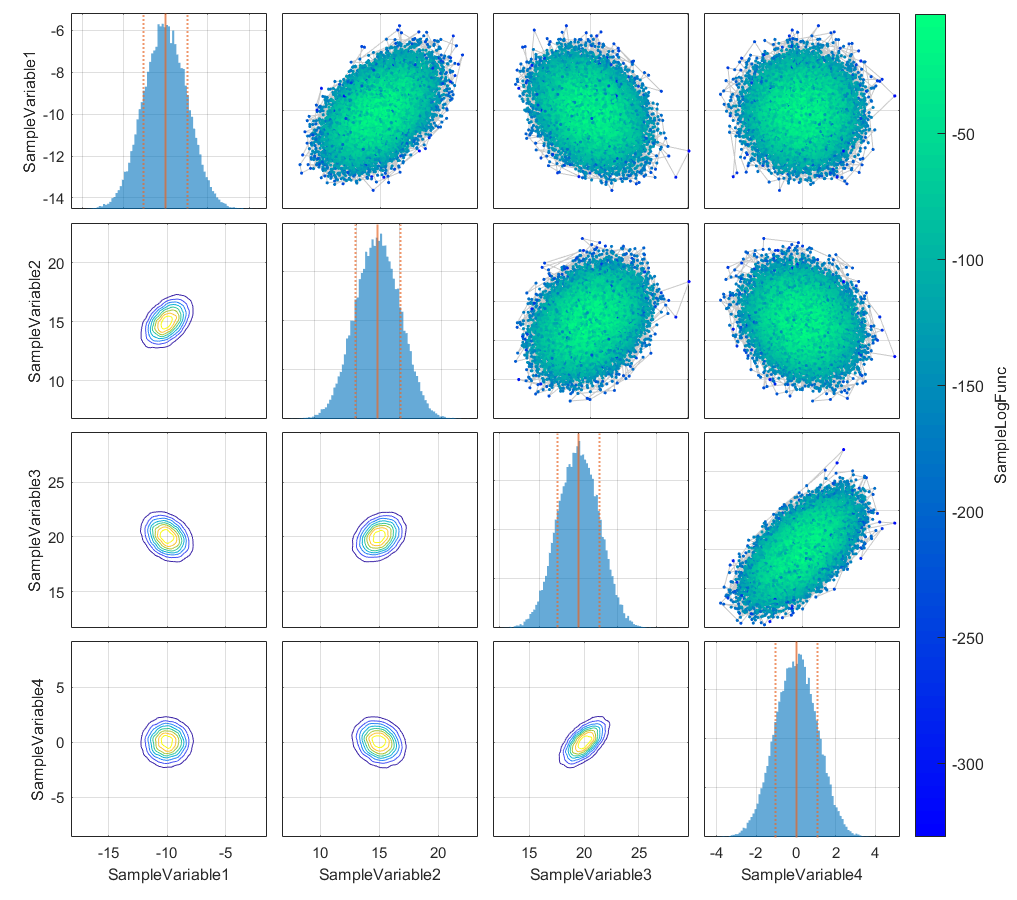

rows = chain.plot.grid.rows;
for i = 1:length(chain.plot.grid.columns)
    avg = mean(chain.df{rows,i+7});
    sigma = std(chain.df{rows,i+7});
    chain.plot.grid.currentFig.subplotList{i,i}.target.vline.kws.lineWidth = 1.5;
    chain.plot.grid.currentFig.subplotList{i,i}.target.make("values",[avg nan]);
    chain.plot.grid.currentFig.subplotList{i,i}.target.vline.kws.lineStyle = ":";
    chain.plot.grid.currentFig.subplotList{i,i}.target.make("values",[avg+sigma nan]);
    chain.plot.grid.currentFig.subplotList{i,i}.target.make("values",[avg-sigma nan]);
end

## Exporting figures to external files

To extract a figure to an external PNG file, try,

chain.plot.grid.exportFig("exportedFigure.png","-m2");

The above command will extract the current active figure to an output file with the relatively medium resoluton as specified by the flag `-m2`. To make the exported figure larger, one could specify the flag `-m4` instead. In addition, to generate a figures with background transparency, the flag `-transparent` can be added to the `exportFig` function call,

% chain.plot.grid.exportFig("exportedFigure.png","-m4 -transparent") % uncomment to export the figure with transparency

**Final Note:**

To see other more sophisticated types of plots that can be automatically made with the ParaMonte visualization tools, visit: [https://www.cdslab.org/paramonte/notes/examples/matlab/mlx/](https://www.cdslab.org/paramonte/notes/examples/matlab/mlx/)